a = csvread('activation_predicted_values.csv')

a =     0.0520    0.1492    0.1621    0.0404    0.0529    0.0883    0.0895    0.0429    0.0466    0.0390    0.0439    0.0400    0.0458    0.2159    0.0745    0.0789    0.0639    0.1477    0.0800    0.0675    0.0688    0.0496    0.0539    0.1269    0.1747    0.0550    0.1958    0.1974    0.0760    0.0550    0.0512    0.1840    0.1874    0.0815    0.0865    0.2766    0.0821    0.1479    0.1032    0.3545    0.0989    0.0391    0.0994    0.1771    0.1571    0.0499    0.0873    0.0453    0.0712    0.0984


nbin = 5;
y = [0 quantile(a, nbin-1) 1]

y =          0    0.1253    0.3656    0.6929    0.8553    1.0000


y = [0 0.1253 0.3656 0.6929 0.8553 1]

y =          0    0.1253    0.3656    0.6929    0.8553    1.0000


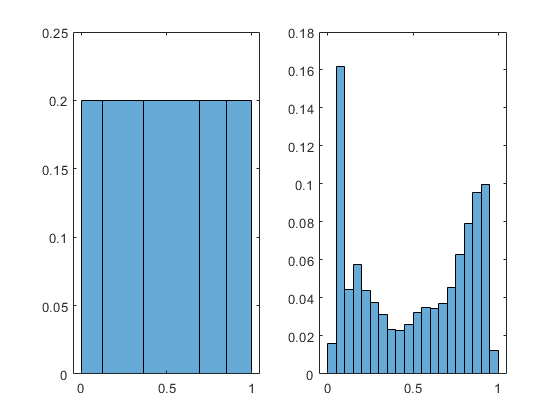


figure(1)
subplot(1,2,1)
histogram(a,y,'Normalization','probability')
subplot(1,2,2)
histogram(a, 'Normalization','probability')


size(find(a >= y(1) & a <= y(2)))

ans =            1        1394


size(find(a >= y(2) & a <= y(3)))

ans =            1        1397


size(find(a >= y(3) & a <= y(4)))

ans =            1        1394


size(find(a >= y(4) & a <= y(5)))

ans =            1        1394


size(find(a >= y(5) & a <= y(6)))

ans =            1        1396
